# Looping Fairground Swing (linearized classical solution)

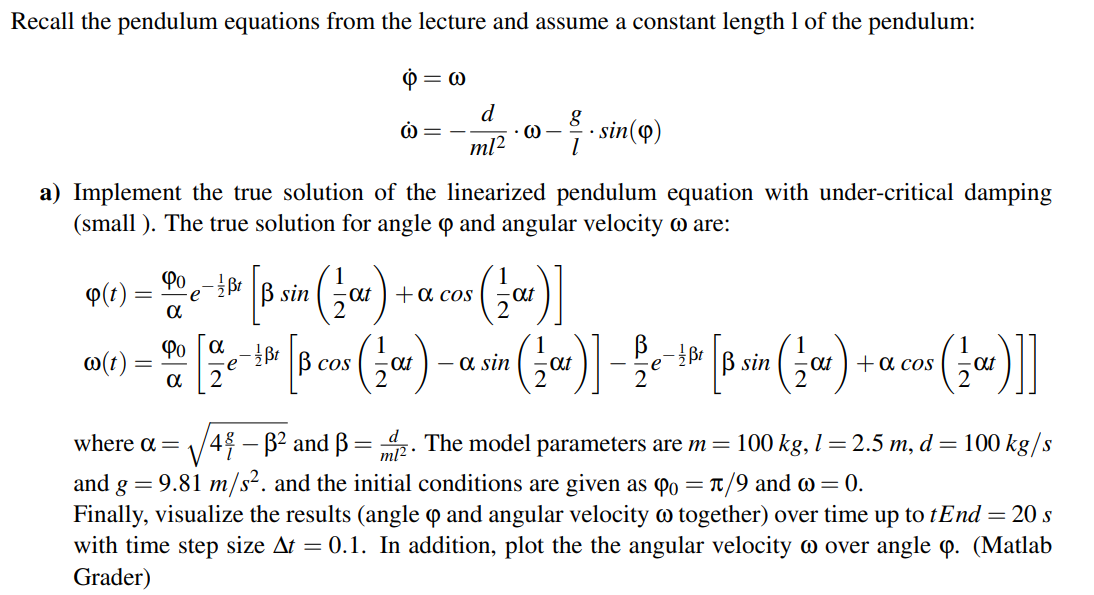

clear all, clc

%function pendulum [theta_0, omega_0] = Pendulum(m, l, d, del_t)

%initial condition
theta_0 = pi/9;
omega_0 = 0;

% simulation Parameters
del_t = 0.1;
t = 0:del_t:100;

% system parameters
d = 100;
l = 2.5;
m = 100;
g = 9.81;

% Governing equations

beta = d/(m*l^2);
alpha = sqrt(4*g/l -beta^2);

## Angular position vs time

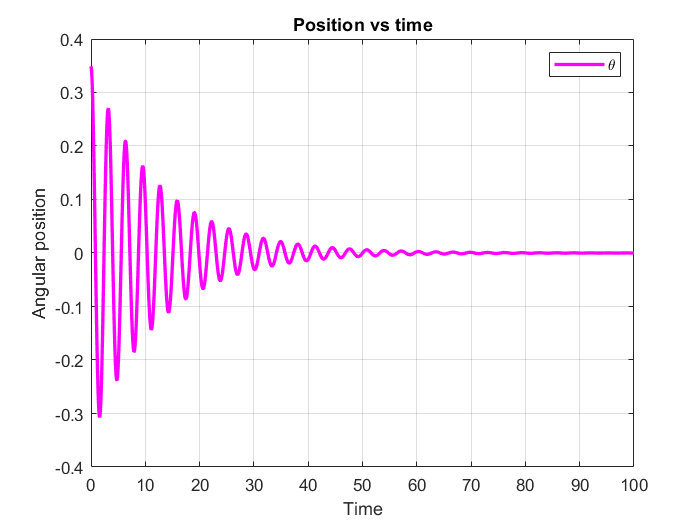

theta = (theta_0 / alpha) * exp(-0.5 * beta.*t) .* (beta* sin(0.5*alpha.*t) + alpha*cos(0.5*alpha.*t));
figure(1)

plot (t, theta, 'm','Linewidth',[2])
title('Position vs time')
xlabel('Time')
ylabel('Angular position')
legend('\theta')
grid on

## Angular velocity vs Time

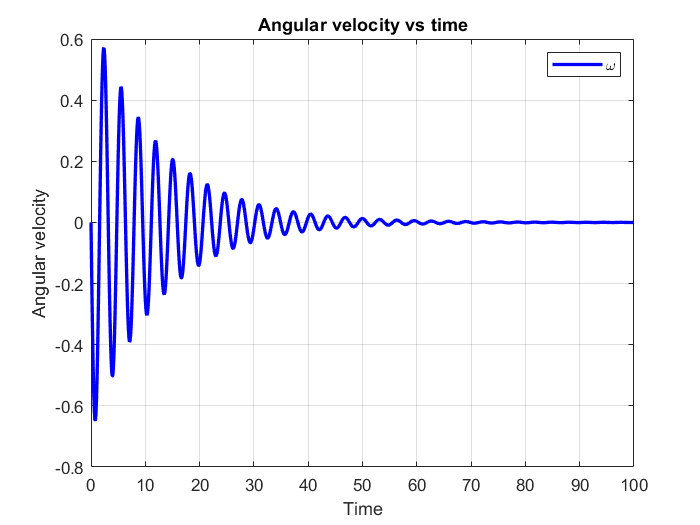

figure(2)

% temporary variables for calculation
a = alpha*(beta*cos(0.5*alpha.*t) - (alpha*sin(0.5*alpha.*t)));
b = beta*(beta*sin(0.5*alpha.*t) + (alpha*cos(0.5*alpha.*t)));
c = exp(-0.5 * beta.*t);
k = (0.5*theta_0 / alpha);

Omega =  k* (c.*a- c.*b);

plot (t,Omega, 'b','Linewidth',[2])
title('Angular velocity vs time')
xlabel('Time')
ylabel('Angular velocity')
legend('\omega')
grid on

## Phase plot

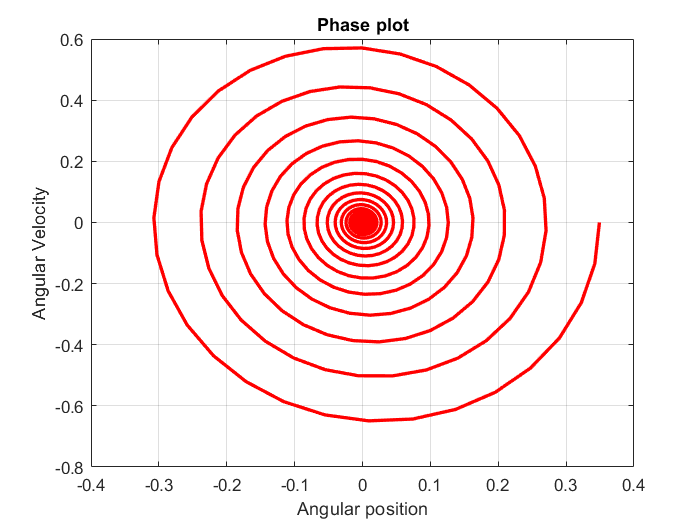

figure(3)

plot (theta,Omega, 'r','Linewidth',[2])
title('Phase plot')
xlabel('Angular position')
ylabel('Angular Velocity')
grid on